# Doppler Processing

## How to extract the Dopper, $f_D$ ?

The Radar Equation Explains that

### 
$$S_{\mathrm{rx}} \left(t\right)=\alpha S_{\mathrm{tx}} \left(t-\frac{2R}{c}\right)=\alpha p\left(t-\frac{2R}{c}\right)e^{\mathrm{j2}\pi F_c \left(t-\frac{2R}{c}\right)}$$


Which is the received Signal formulae

If the target is moving then, R is not constant. It is a function of t.

$R=R_0 -\mathrm{vt}$ where v > 0 for incoming target

We substitude the value of R 


$$S_{\textrm{rx}} \left(t\right)=s_{\textrm{tx}} \alpha \left(t-\frac{2\left(R_0 -\mathrm{vt}\right)}{c}\right)=\alpha p\left(t-\frac{2\left(R_0 -\mathrm{vt}\right)}{c}\right)e^{\textrm{j2}\pi F_c \left(t-\frac{2\left(R_0 -\mathrm{vt}\right)}{c}\right)}$$


assuming that $R_0 >>\mathrm{vt}$

then the formulae becomes

## 
$$S_{\mathrm{rx}} \left(t\right)=\alpha s_{\mathrm{rx}} \left(t-\frac{2R_0 }{c}\right)e^{\mathrm{j2}\pi F_c t} e^{-\mathrm{j4}\pi F_c \frac{R_0 }{c}} e^{\mathrm{j2}\pi F_c \frac{2\mathrm{vt}}{c}}$$


Where $F_c$is the carrier Frequency

## $e^{-\textrm{j4}\pi F_c \frac{R_0 }{c}}$ is constant 

## $e^{\textrm{j2}\pi F_c t}$ disappears with basebanding

## 
$$e^{\textrm{j2}\pi F_c \frac{2v\textrm{t}}{c}} =e^{j\pi \frac{4\mathrm{vt}}{\lambda }} =e^{j\pi {2f}_d t}$$


### 
$$S_{\mathrm{rx}} \left(t\right)\approx \alpha p\left(t-\frac{2R}{c}\right)e^{\mathrm{j2}\pi F_c t} e^{\frac{-\mathrm{j4}\pi R_0 }{\lambda }} e^{\mathrm{j2}\pi f_d t}$$


How could  the recived power knows the dopper ?

Use pulse - Dopper technique : Observe target through multiple pulses spaced at a constant interval called the Pulse Repetition interval(PRI)

For pulse n after pulse compression(MF), the signal across range R0 

## 
$$S_{\mathrm{base},\mathrm{Mf}} \left(\mathrm{nT}\right)\approx e^{\frac{-\mathrm{j4}\pi R}{\lambda \;}} e^{2\pi f_d \mathrm{nT}}$$
 

Slow time sampling

## Doppler Processing

## 
$$e^{j2\pi f_d \mathrm{nT}}$$
 

- Sampling interval is T and sampling rate or frequency is the PRF = $\frac{1}{T}$

- For nyquist sampling, the maximum Doppler we can detect without aliasing is $\frac{\mathrm{PRF}}{2}$

- The maximum unambigouts velocity is $\frac{\lambda \cdot \mathrm{PRF}}{4}$

Q. Prove that the maximum unambious velocitiy is $\frac{\lambda \cdot \mathrm{PRF}}{4}$

# Analysis Example

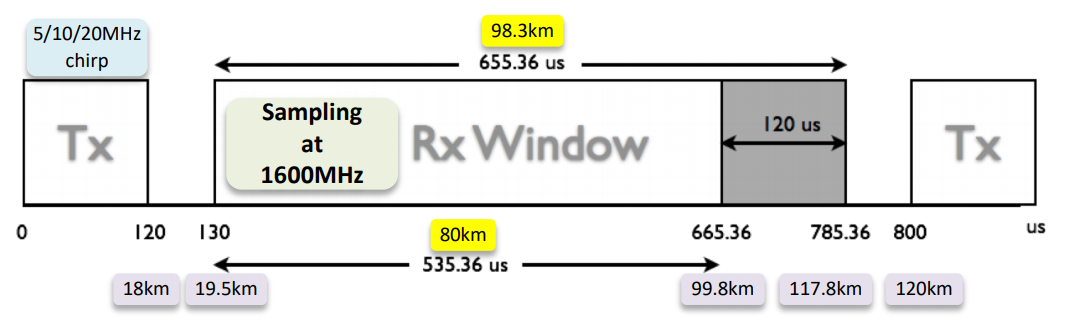

The process

- 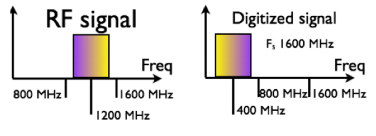 RF signals gets sampled in a rate of 1600Mhz

- The original Signal 

- The sampled signal flips ?

Why the signal Filps ?

Let's say that 1Hz signal of amp 1, and 0.5Hz signal of amp 3 , and 0.2 Hz signal of amp 7 is combined 

signal_1Hz = ones(1,100);
signal_05Hz =zeros(1,100); signal_05Hz(1,1:2:100)= 3;

signal_02Hz =zeros(1,100); signal_02Hz(1,1:5:100)= 7

signal_02Hz =      7     0     0     0     0     7     0     0     0     0     7     0     0     0     0     7     0     0     0     0     7     0     0     0     0     7     0     0     0     0     7     0     0     0     0     7     0     0     0     0     7     0     0     0     0     7     0     0     0     0


sig = signal_1Hz + signal_05Hz + signal_02Hz;
% if we sample at the rate of 02Hz then
sam=sig(1,1:5:100)

sam =     11     8    11     8    11     8    11     8    11     8    11     8    11     8    11     8    11     8    11     8


%The result shows that  1 Hz  = [ 1 1 1 1 1 1 1 1 1 1 1....]
                      %0.5Hz  = [ 1 0 1 0 1 0 1 0 1 0 1 0  ]
                      %0.2Hz  = [ 1 1 1 1 1 1 1 1 1 1 1 1  ] ->  1 space ==
                      %5 seconds
                   

## Fundamental sampling Theorem : To measure a frequency, $f_D$ it is necessary to sample at a frequency of at least 2$f_d$


$$\begin{array}{l}
2f_D =\mathrm{PRF}\\
V=\frac{-f\lambda }{2}
\end{array}$$


Therefore, $V_{\mathrm{max}} =\frac{\mathrm{PRF}\cdot \lambda }{4}$